# Template Gallery

We've created a gallery containing a number of interesting and useful quantum graphs. 

Each template consists of two MATLAB functions stored as mfiles.

- `<TEMPLATE>.m` This file can be called on its own, or using the wrapper function `quantumGraphFromTemplate`. Each template file has default settings, set in an `arguments` block, or else the parameters can be set as optional arguments, using name-value pairs.

- `<TEMPLATE>PlotCoords.m` Sets the plot coordinates. The file  `quantumGraphFromTemplate` calls both parts of the template together.

## Star

Defaults

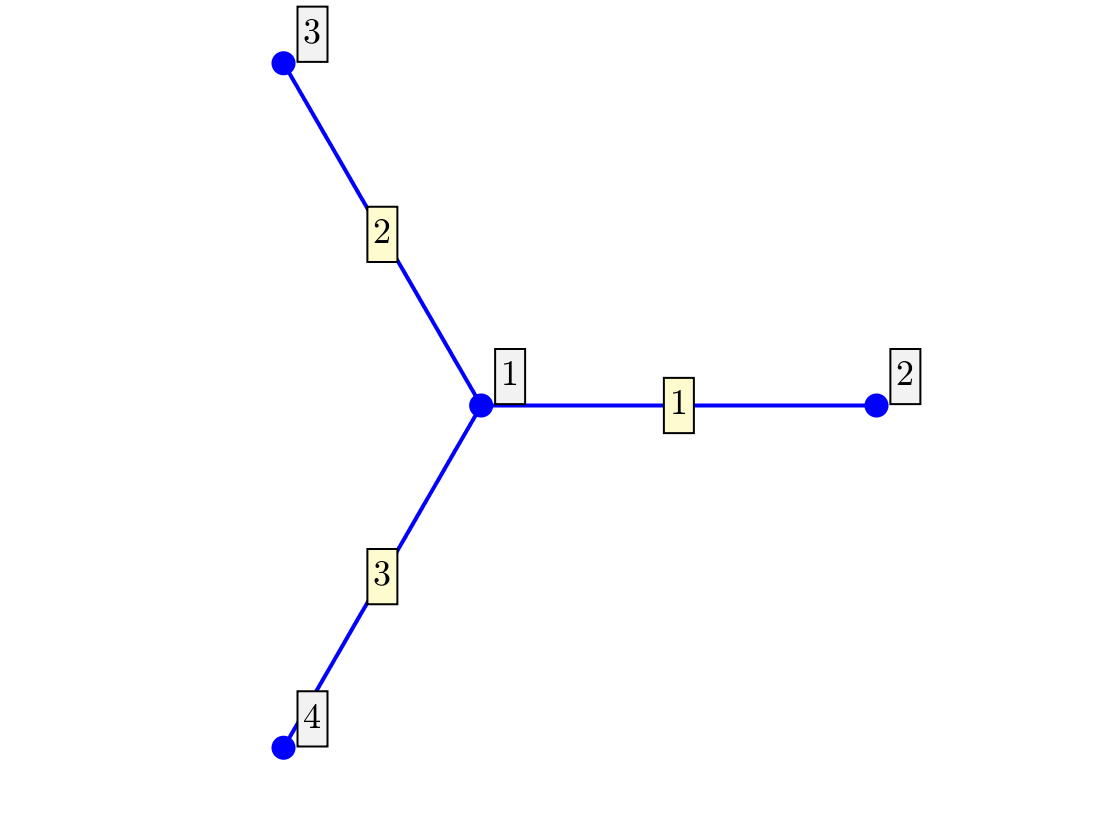

Phi=quantumGraphFromTemplate('star');
Phi.plot('layout')

A 6-pointed star with edge lengths chosen at random between 5 and 10 and Dirichlet conditions on the end of the final two edges. Plot the ground state of the Laplacian

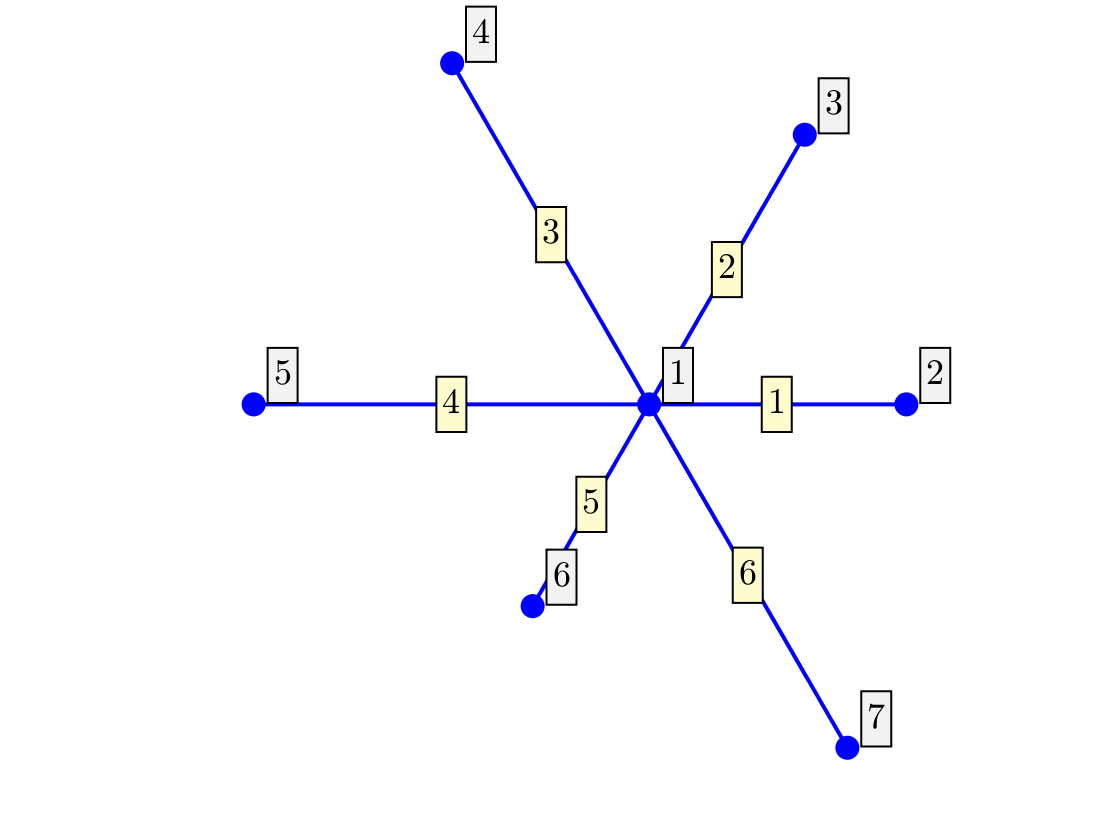

n=6;
L=5*(1+rand(n,1));
robinCoeff=zeros(n+1,1); robinCoeff(n:n+1)=nan;
Phi=quantumGraphFromTemplate('star','n',6,'LVec',L,'robinCoeff',robinCoeff);
Phi.plot('layout')

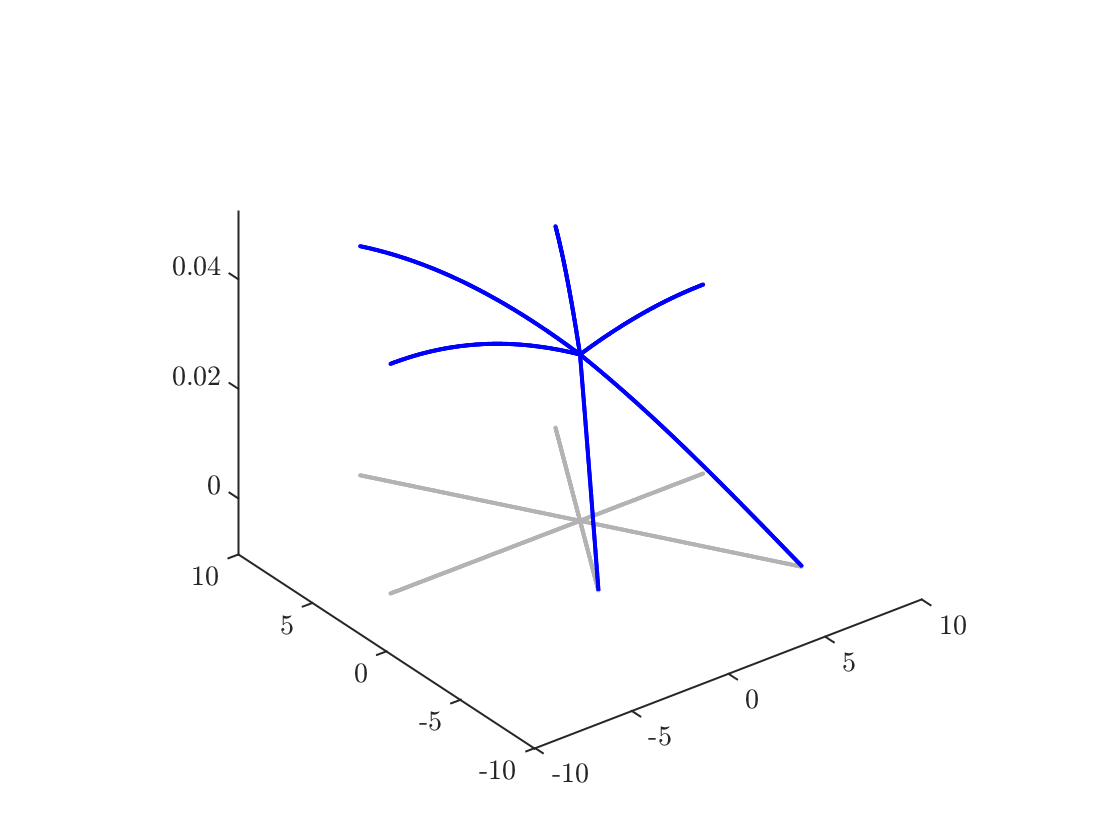

figure;
[V,lambda]=eig(Phi);
Phi.plot(V(:,1))

title('Ground state for a random star graph with 2 dirichlet vertices')

## Dumbbell

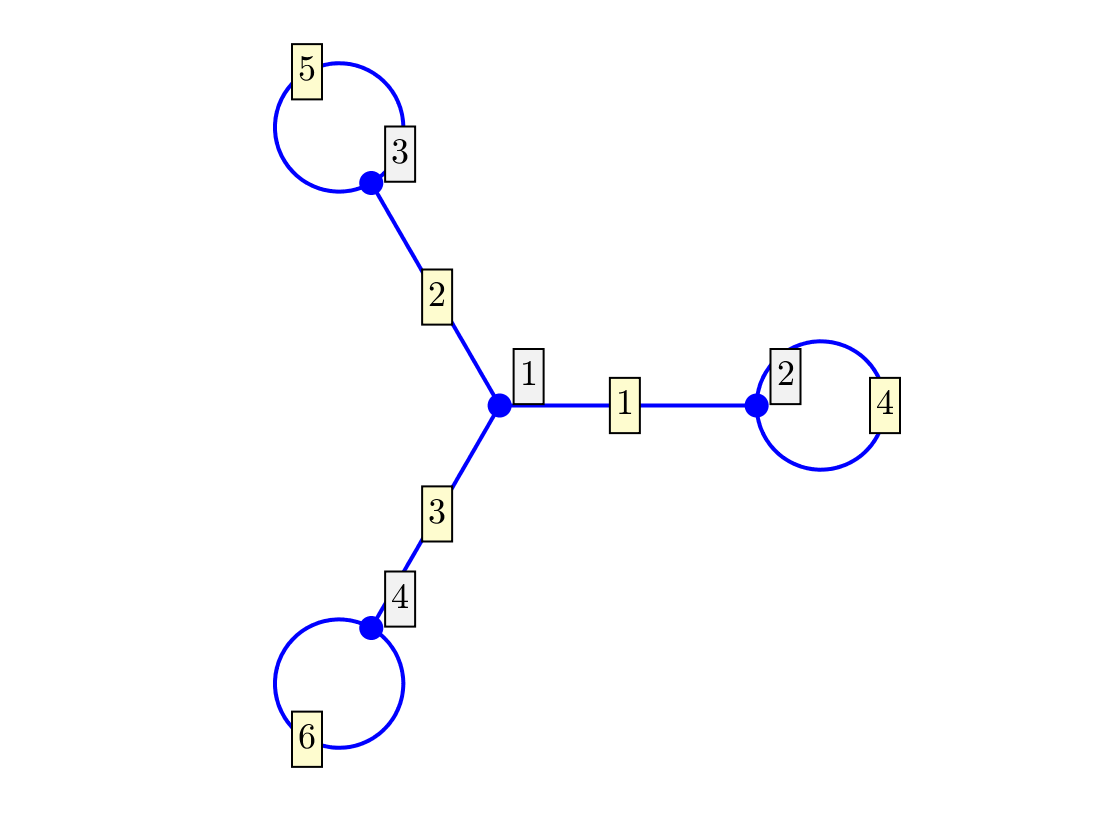

Phi=quantumGraphFromTemplate('dumbbell');
Phi.plot('layout')

## nbell

Generalization of the dumbbell consisting of $n$ lollipops/tadpoles joined by their stems. By default $n=3$ and all the lollipops are identical, but they need not be.

Phi=quantumGraphFromTemplate('nbell');

Phi =   quantumGraph with properties:

                 qg: [1×1 digraph]
     discretization: 'Uniform'
    laplacianMatrix: [103×103 double]


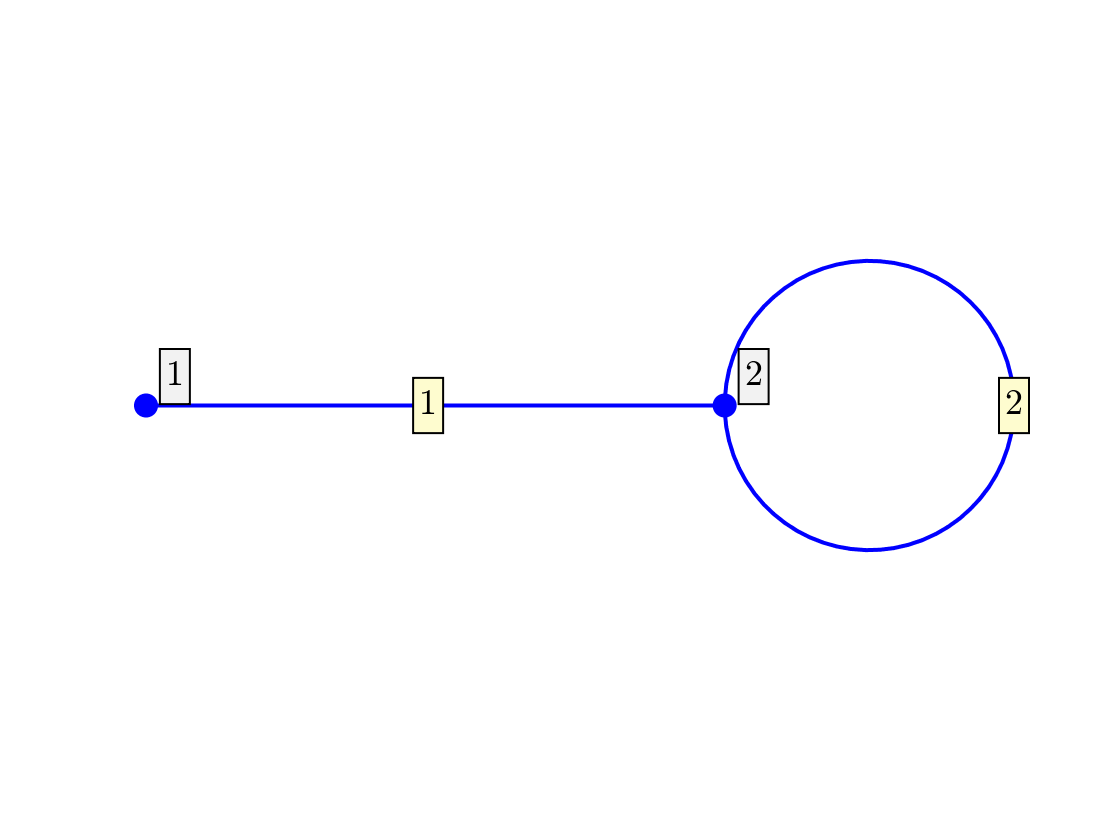

Phi.plot('layout')

If $n=1$we recover the lollipop/tadpole

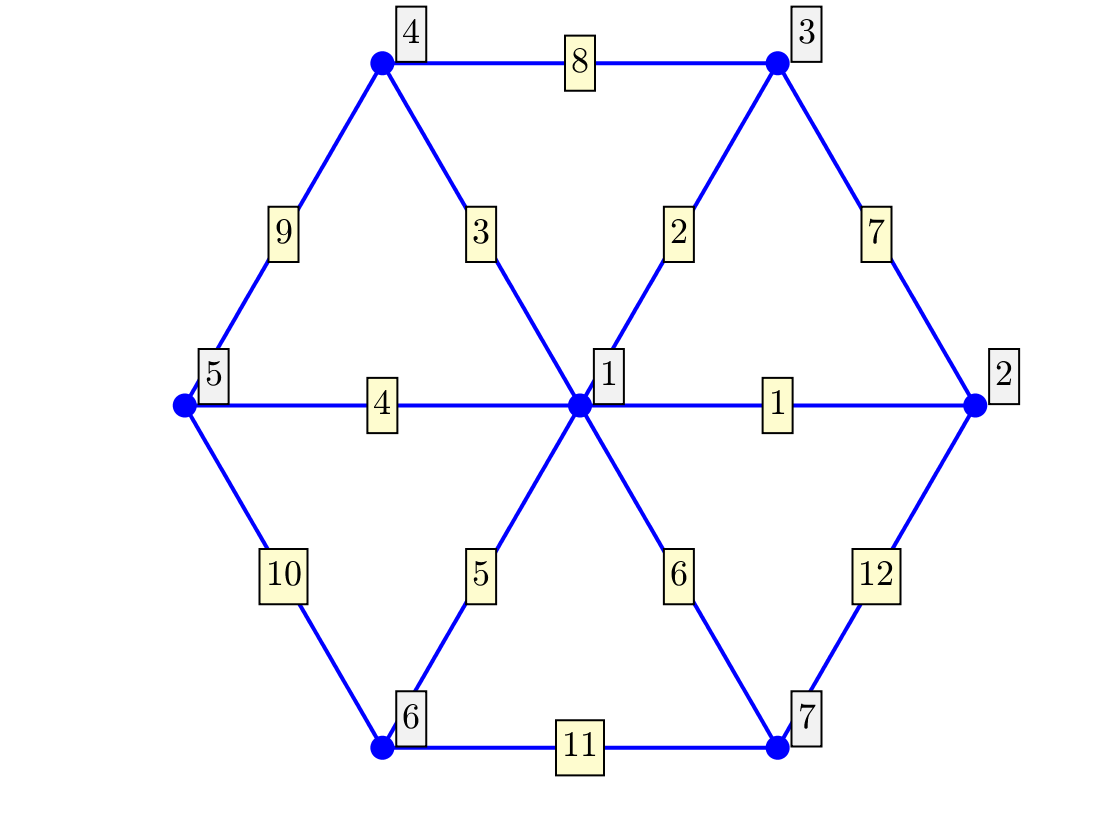

Phi=quantumGraphFromTemplate('nbell','nBells',1);
Phi.plot('layout')

## Wheel

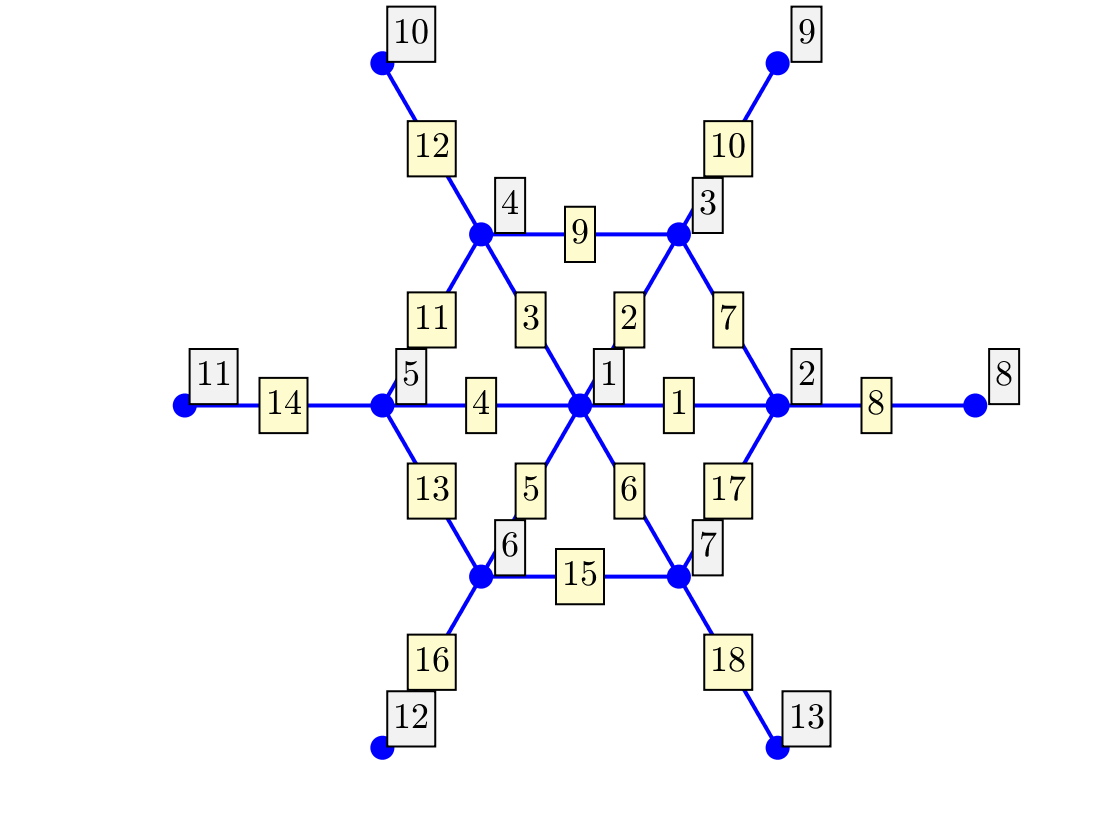

Phi=quantumGraphFromTemplate('wheel');
Phi.plot('layout')

## Helm

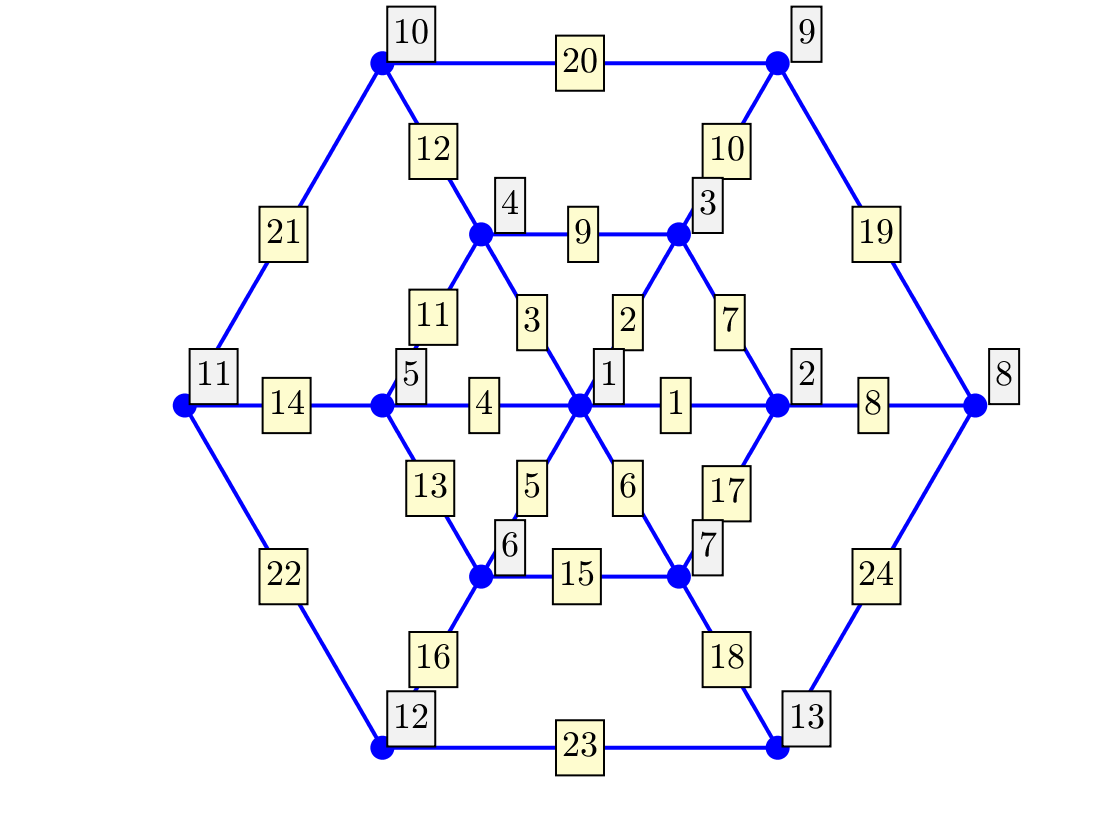

Phi=quantumGraphFromTemplate('helm');
Phi.plot('layout')

## Spiderweb

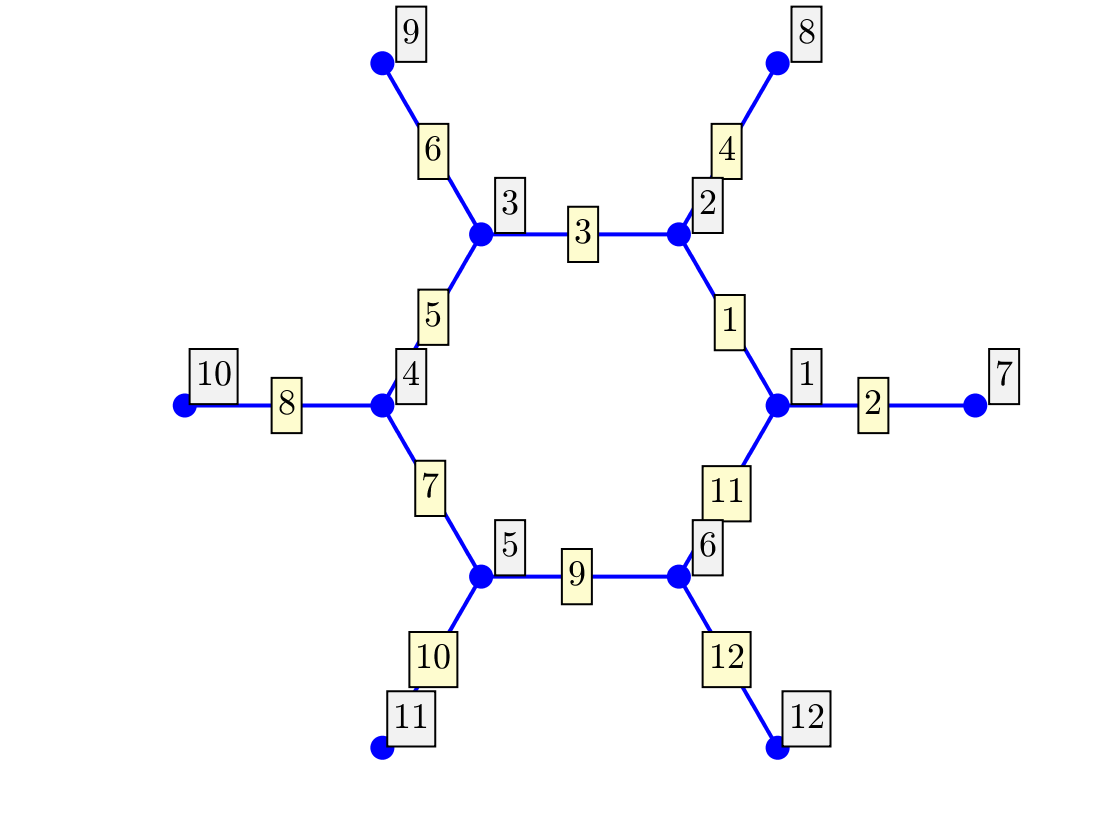

Phi=quantumGraphFromTemplate('spiderWeb');
Phi.plot('layout')

## Sunlet

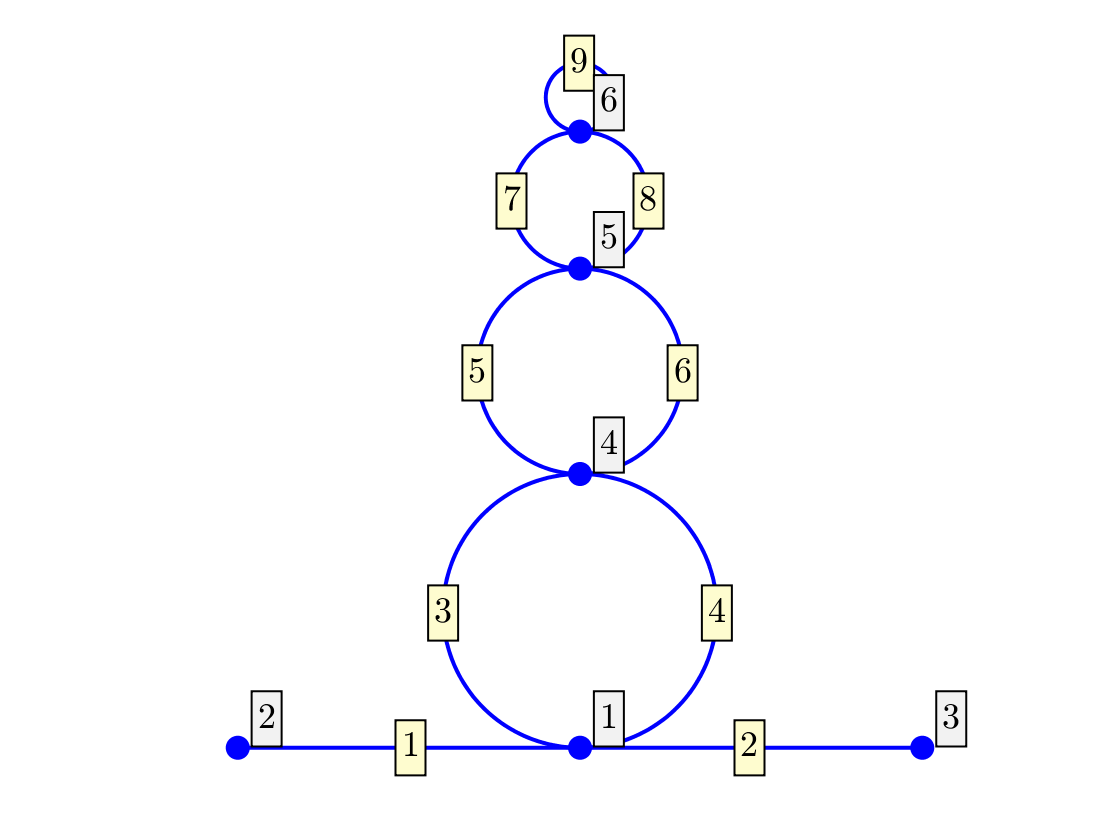

Phi=quantumGraphFromTemplate('sunlet');
Phi.plot('layout')

## Bubble Tower

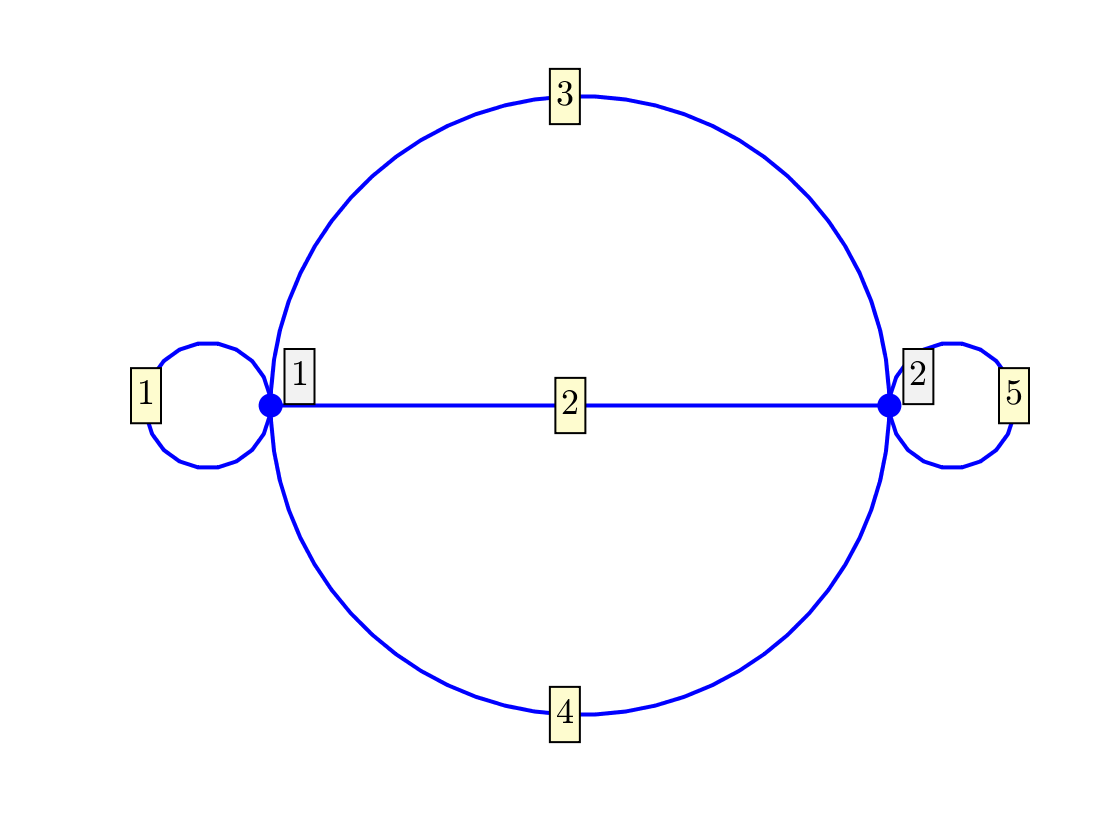

Phi=quantumGraphFromTemplate('bubbleTower','rVec',[4 3 2 1]);
Phi.plot('layout')

## Berkolaiko-Marzuola Pelinovsky

This is the example from 

 Berkolaiko, G., Marzuola, J. L. & Pelinovsky, D. E. Edge-localized states on quantum graphs in the limit of large mass. *Arxiv* (2019), to appear in *Annales de l’Institut Henri Poincare*.

Phi=quantumGraphFromTemplate('BMP');
Phi.plot('layout')